# 参数

clear,clc
%全交换面积计算参数
Lr = 4.1;%辐射管长度
Ws = 3.6;%钢板宽
Wfur = 4.6;%炉宽
epsilon_r = 0.8;%黑度
rho_r = 0.2;%反射率
epsilon_w = 0.5;
rho_w = 0.5;
epsilon_s = 0.75;
rho_s = 0.25;
%序号 直径 段长 h1 h2 辐射管间隔数组 功率数组
cellZoneInfo = {1,0.3,8.7,0.65,0.91,[2700 600 600 600 600 600 1200 600 1200],[115 150 115 150 115 150 115 150 115/2];
         2,0.3,7.2,0.65,0.91,[600 600 600 600 600 600 600 600 600 600 600 600],[115/2 150 115 150 115 150 115 150 115 150 115 150 95/2];
         3,0.28,7.2,0.66,0.92,[600 600 600 600 600 600 1200 600 1200 600],[95/2 120 95 120 95 120 95 120 95 120 95/2];
         4,0.28,7.2,0.66,0.92,[600 2400 600 600 1200 600 600 600],[95/2 120 95 120 95 120 95 120 95/2];
         5,0.28,7.2,0.66,0.92,[600 1200 600 1200 600 1200 600 1200],[95/2 120 95 120 95 120 95 120 95/2];
         6,0.28,7.2,0.66,0.92,[1200 1200 1200 1200 1200 1200],[95/2 120 95 120 95 120 95/2];
         7,0.28,6.6,0.66,0.92,[1200 2400 1800 1200],[95/2 120 95 120 95/2];
         8,0.208,7.2,0.696,0.956,[1800 1800 1800 1800],[95/2 80 55 80 55/2];
         9,0.208,7.2,0.696,0.956,[1800 1800 1800 1800],[55/2 80 55 80 55/2];
         10,0.208,7.2,0.696,0.956,[1800 1800 1800 1800],[55/2 80 55 80 55/2];
         11,0.208,9.3,0.696,0.956,[1800 1800 1800 1800 2100],[55/2 80 55 120 95];}

cellZoneInfo = 11×7 cell 数组
    {[ 1]}    {[0.3000]}    {[8.7000]}    {[0.6500]}    {[0.9100]}    {[         2700 600 600 600 600 600 1200 600 1200]}    {[                    115 150 115 150 115 150 115 150 57.5000]}
    {[ 2]}    {[0.3000]}    {[7.2000]}    {[0.6500]}    {[0.9100]}    {[600 600 600 600 600 600 600 600 600 600 600 600]}    {[57.5000 150 115 150 115 150 115 150 115 150 115 150 47.5000]}
    {[ 3]}    {[0.2800]}    {[7.2000]}    {[0.6600]}    {[0.9200]}    {[      600 600 600 600 600 600 1200 600 1200 600]}    {[            47.5000 120 95 120 95 120 95 120 95 120 47.5000]}
    {[ 4]}    {[0.2800]}    {[7.2000]}    {[0.6600]}    {[0.9200]}    {[              600 2400 600 600 1200 600 600 600]}    {[                   47.5000 120 95 120 95 120 95 120 47.5000]}
    {[ 5]}    {[0.2800]}    {[7.2000]}    {[0.6600]}    {[0.9200]}    {[            600 1200 600 1200 600 1200 600 1200]}    {[                   47.5000 120 95 120 95 120 95 120 47.5000]}
    {[ 6]}    {[0.2800]}   


%三元法计算参数
%初(xia)始(gei)化区域温度场
Tw_init = [700 720 740 760 780 800 820 840 860 870 870] + 273.15 + 100;
Ts_1_init = [150 250 420 555 666 777 820 835 850 870 870] + 273.15;
% Ts_1_init = [350 550 620 755 866 977 1020 1035 1050 1070 1070] + 273.15;

Lfur = 82.2;%炉长,m
ths = 50/1000;%板厚,m
Time_heat = 80 * 60;%加热时间,s
Vs = Lfur / Time_heat;%物料速度
Thw = 0.35;%炉墙厚度
lambda_w = 0.138*250/300+0.15*50/300;%炉墙导热系数
Cp_w = 1.12 * 1000;%炉墙比热 J/(kg*k)
density_w = 190*250/300 + 128*50/300;%炉围密度
hw = 15;%炉墙自然对流换热系数
Temp_out = 30+273.15;%环境温度,k
density_s = 7860;
sigma = 5.67*10^(-8);%斯忒藩-玻尔兹曼常数
N = 10;%层数
s_timeStep = 1000;%时间步长节点数


# 全交换面积calc  1.1ver

- **1.0 ver:**单区域计算基本代码

- **1.1 ver:**循环计算多区域

**Todo:**辐射管黑度影响研究，完整性修正系数研究 

SR = zeros(1,length(cellZoneInfo));
SW = zeros(1,length(cellZoneInfo));
WR = zeros(1,length(cellZoneInfo));


for i = 1:length(cellZoneInfo)

    %计算
    S = cellZoneInfo{i,6}./1000;%辐射管间隔数组
    d = cellZoneInfo{i,2};%辐射管直径
    L = cellZoneInfo{i,3};%段长
    h1 = cellZoneInfo{i,4};%见函数
    h2 = cellZoneInfo{i,5};
    kr = Lr/Wfur;%辐射管长度系数
    ks = Ws/Wfur;%钢板宽度系数

    xrp = zeros(1,length(S));
    for j = 1:length(S)
        if S(j) == 2.7 || S(j) == 2.1
            xrp(j) = (d/2)/S(j)*atan(S(j)/(d/2));
        else
            xrp(j) = S(j)/(pi*d)*(1+d/S(j)*acos(d/S(j))-(1-(d/S(j))^2)^(1/2));
        end
    end
    %加权辐射管对假想面角系数
    Xrp = 0;
    for j = 1:length(xrp)
        Xrp = Xrp+S(j)/L*xrp(j);
    end
    %角系数

    Xp1w2 = phi_p1_w2(Wfur,L,h1) + phi_p2_w1(Wfur,L,h1);
    Xp2s = phi_p2_s(Wfur,L,h2);
    Xp2w1 = phi_p2_w1(Wfur,L,h2);
    
    % 论文中修正的角系数
    % Xrs = Xrp * 1/kr * Xp2s * ks;%计算Xrs
    Xrw = Xrp * 1/kr *Xp1w2 + Xrp * 1/kr *Xp2w1;
    Xrr = 1 - 2 * Xrp;%计算Xrr
    % Xrr = 1 - Xrw - Xrs;%完整性计算Xrr
    Xrs = 1 - Xrw - Xrr;%完整性计算Xrs
    
    %不修正的角系数
    % Xrs = Xrp * Xp2s ;
    % Xrw = Xrp *Xp1w2 + Xrp *Xp2w1;
    % Xrr = 1 - 2 * Xrp;

    Fs = L*Ws;
    Fw = L*Wfur+L*h1*2+L*h2*2;
    Fr = pi*d*length(S)*Lr;

    Xss= 0;
    Xsr = Xrs * Fr/Fs;
    Xsw = 1 - Xsr - Xss;
    Xwr = Xrw * Fr/Fw;
    Xws = Xsw * Fs/Fw;
    Xww = 1 - Xwr - Xws;
    %直接交换面积
    rr = Fr * Xrr;
    rw = Fr * Xrw;
    rs = Fr * Xrs;
    wr = Fw * Xwr;
    ww = Fw * Xww;
    ws = Fw * Xws;
    sr = Fs * Xsr;
    sw = Fs * Xsw;
    ss = Fs * Xss;

    %全交换面积

    SR(i) = calculate_SR(Fr, Fw, Fs, epsilon_r, epsilon_s, rho_r, rho_w, rho_s, Xrr, Xws, Xsr, Xww, Xwr);
    SW(i) = calculate_SW(Fr, Fw, Fs, epsilon_w, epsilon_s, rho_r, rho_w, rho_s, Xrr, Xws, Xwr, Xsr, Xww);
    WR(i) = calculate_WR(Fr, Fw, Fs, epsilon_r, epsilon_w, rho_r, rho_w, rho_s, Xrr, Xwr, Xsr, Xsw, Xww);
    
end
% SR = SR + 100;
% SW = SW + 100;
% WR = WR + 100;

RS = SR

RS =     8.1268   11.9787   10.1070    8.5788    8.5809    6.8442    4.8369    3.7192    3.7192    3.7192    3.8903


WS = SW

WS =    11.9749    5.8865    7.3590    8.5106    8.5090    9.7742    9.9752   12.0063   12.0063   12.0063   16.1500


RW = WR

RW =     9.1121   13.4812   11.2886    9.5120    9.5145    7.5320    5.2260    4.0828    4.0828    4.0828    4.3991


SR

SR =     8.1268   11.9787   10.1070    8.5788    8.5809    6.8442    4.8369    3.7192    3.7192    3.7192    3.8903


SW

SW =    11.9749    5.8865    7.3590    8.5106    8.5090    9.7742    9.9752   12.0063   12.0063   12.0063   16.1500


WR

WR =     9.1121   13.4812   11.2886    9.5120    9.5145    7.5320    5.2260    4.0828    4.0828    4.0828    4.3991


# 三元法calc   1.1ver

- **1.0 ver**:常物性计算基本代码

- **1.1 ver**:钢坯变物性计算追加

- **1.2 ver**:炉围常物性一维差分追加，施工中：

**Todo:**已确定炉围初始温度场对出炉钢温有较大影响，黑度增加对炉围钢温无影响疑似与无炉围一维差分计算有关，现停止更改无炉围一维差分修正温度的版本，上传分支并增加炉围一维计算。

%初始化
Tw_zone = zeros(1,length(cellZoneInfo));
Tr_zone = zeros(1,length(cellZoneInfo));
Ts_zone = zeros(1,length(cellZoneInfo));

phi_r = zeros(1,length(cellZoneInfo));

Temp_inlet = zeros(N+1,length(cellZoneInfo));
Temp_inlet(:,1) = 30 + 273.15;
Temp_total = zeros(length(cellZoneInfo),s_timeStep*length(cellZoneInfo));

Nw = 5;

for i = 1:length(cellZoneInfo)

    phi_r(i) = sum(cellZoneInfo{i,7})*1000;%W
    Ts_1 = Ts_1_init(i);%段内物料表面初始温度
    Ts_2 = 0;%初始化，进循环用
    L = cellZoneInfo{i,3};%段长
    Time_zone = L / Vs;%段内时间

    Tw_1 = Tw_init(i);
    Tw_2 = 0;%初始化，进循环
    
    
    while(abs((Ts_2 - Ts_1)/Ts_1)>=0.001)

        Ts_1 = Ts_2;%迭代

        while (abs((Tw_2 - Tw_1)/Tw_1)>=0.001)

            Tw_1 = Tw_2;%迭代

        %能量平衡解Tr
            syms Tr;
            f1 = sigma*RW(i)*(Tr^4 - Tw_1^4) + sigma*RS(i)*(Tr^4 - Ts_1^4) == phi_r(i);
            Tr = solve(f1,Tr);
            Tr = vpa(Tr);
            Tr= Tr(imag(Tr) == 0 & real(Tr) > 0);
    
        %能量平衡解Tw   
            syms Tw_2;
            f2 = sigma*SW(i)*(Ts_1^4 - Tw_2^4) + sigma*RW(i)*(Tr^4 - Tw_2^4) == Fw*(Tw_2 - Temp_out)/(1/hw+Thw/lambda_w);
            Tw_2 = solve(f2,Tw_2);
            Tw_2 = vpa(Tw_2);
            Tw_2= Tw_2(imag(Tw_2) == 0 & real(Tw_2) > 0);
        end
        
        Tw_1 = Tw_2;

    %差分求炉围温度
        % Tw_zone_init = zeros(1,Nw+1) + Tw_1;
        % while(abs((Tw_2 - Tw_1)/Tw_1)>=0.01)
        %     qw_in = abs(sigma*SW(i)*(Ts_1^4 - Tw_1^4) + sigma*RW(i)*(Tr^4 - Tw_1^4));
        %     qw_out = 
        % end


    %求钢坯表面热流    
        qcon_s = -(sigma*RS(i)*(Ts_1^4 - Tr^4) + sigma*WS(i)*(Ts_1^4 - Tw_1^4))/Fs%钢坯表面热流密度
        % RS(i)*(Ts_1^4 - Tr^4)
        % WS(i)*(Ts_1^4 - Tw_1^4)
    %差分求物料温度   
        T = Temp_inlet(:,i);
        delta_t = Time_zone / s_timeStep;%时间步长
        delta_x = ths/(2*N);%空间步长
        Temp_zone = zeros(length(cellZoneInfo),s_timeStep);
        for j = 1:s_timeStep
            T = TDMA_s(qcon_s,N,density_s,delta_t,delta_x,T);
            Temp_zone(:,j) = T;
        end
    
        Ts_2 = sum(Temp_zone(1,:))/s_timeStep;%热流反算物料表面温度
    
        % if abs((Ts_2 - Ts_1)/Ts_1)<=0.001
        %     break;
        % end
        Tw_2 = 0;%进循环
    end
    
    % sprintf('%.3e', phi_r(i)/sigma)
    % sprintf('%.3e', RW(i)*Tw^4)
    % sprintf('%.3e', RS(i)*Ts_2^4)

    Temp_inlet(:,i+1) = T
    Tw_zone(i) = Tw_1 ;%K
    Tr_zone(i) = Tr ;%K
    Ts_zone(i) = Ts_2 ;%K
    Temp_total(:,1+(i-1)*s_timeStep:i*s_timeStep) = Temp_zone;%K

end

$$qcon\_s = 32858.349014622521157648729339385$$

$$qcon\_s = 32850.498188068981077403878129913$$

Temp_inlet =   303.1500  475.2146         0         0         0         0         0         0         0         0         0
  303.1500  473.3523         0         0         0         0         0         0         0         0         0
  303.1500  471.6909         0         0         0         0         0         0         0         0         0
  303.1500  470.2287         0         0         0         0         0         0         0         0         0
  303.1500  468.9644         0         0         0         0         0         0         0         0         0
  303.1500  467.8966         0         0         0         0         0         0         0         0         0
  303.1500  467.0243         0         0         0         0         0         0         0         0         0
  303.1500  466.3467         0         0         0         0         0         0         0         0         0
  303.1500  465.8632         0         0         0         0         0         0         0         

$$qcon\_s = 46519.930634610920768866737786091$$

$$qcon\_s = 46496.964133176300945290103599258$$

Temp_inlet =   303.1500  475.2146  659.0564         0         0         0         0         0         0         0         0
  303.1500  473.3523  655.9412         0         0         0         0         0         0         0         0
  303.1500  471.6909  653.1676         0         0         0         0         0         0         0         0
  303.1500  470.2287  650.7309         0         0         0         0         0         0         0         0
  303.1500  468.9644  648.6270         0         0         0         0         0         0         0         0
  303.1500  467.8966  646.8526         0         0         0         0         0         0         0         0
  303.1500  467.0243  645.4047         0         0         0         0         0         0         0         0
  303.1500  466.3467  644.2809         0         0         0         0         0         0         0         0
  303.1500  465.8632  643.4795         0         0         0         0         0         0         

$$qcon\_s = 31537.013169168657776186499820712$$

$$qcon\_s = 31466.441824169025174132996318228$$

Temp_inlet =   303.1500  475.2146  659.0564  766.5973         0         0         0         0         0         0         0
  303.1500  473.3523  655.9412  764.2276         0         0         0         0         0         0         0
  303.1500  471.6909  653.1676  762.1211         0         0         0         0         0         0         0
  303.1500  470.2287  650.7309  760.2733         0         0         0         0         0         0         0
  303.1500  468.9644  648.6270  758.6799         0         0         0         0         0         0         0
  303.1500  467.8966  646.8526  757.3374         0         0         0         0         0         0         0
  303.1500  467.0243  645.4047  756.2430         0         0         0         0         0         0         0
  303.1500  466.3467  644.2809  755.3942         0         0         0         0         0         0         0
  303.1500  465.8632  643.4795  754.7892         0         0         0         0         0         

$$qcon\_s = 25185.847301094223225400313825125$$

$$qcon\_s = 25070.896904193378285910304598851$$

Temp_inlet =   303.1500  475.2146  659.0564  766.5973  845.0734         0         0         0         0         0         0
  303.1500  473.3523  655.9412  764.2276  843.0115         0         0         0         0         0         0
  303.1500  471.6909  653.1676  762.1211  841.1725         0         0         0         0         0         0
  303.1500  470.2287  650.7309  760.2733  839.5545         0         0         0         0         0         0
  303.1500  468.9644  648.6270  758.6799  838.1557         0         0         0         0         0         0
  303.1500  467.8966  646.8526  757.3374  836.9747         0         0         0         0         0         0
  303.1500  467.0243  645.4047  756.2430  836.0100         0         0         0         0         0         0
  303.1500  466.3467  644.2809  755.3942  835.2608         0         0         0         0         0         0
  303.1500  465.8632  643.4795  754.7892  834.7262         0         0         0         0         

$$qcon\_s = 25185.824322038371621633993285584$$

$$qcon\_s = 25029.80403413778609803521852084$$

Temp_inlet =   303.1500  475.2146  659.0564  766.5973  845.0734  922.2372         0         0         0         0         0
  303.1500  473.3523  655.9412  764.2276  843.0115  920.0663         0         0         0         0         0
  303.1500  471.6909  653.1676  762.1211  841.1725  918.1231         0         0         0         0         0
  303.1500  470.2287  650.7309  760.2733  839.5545  916.4079         0         0         0         0         0
  303.1500  468.9644  648.6270  758.6799  838.1557  914.9210         0         0         0         0         0
  303.1500  467.8966  646.8526  757.3374  836.9747  913.6625         0         0         0         0         0
  303.1500  467.0243  645.4047  756.2430  836.0100  912.6326         0         0         0         0         0
  303.1500  466.3467  644.2809  755.3942  835.2608  911.8314         0         0         0         0         0
  303.1500  465.8632  643.4795  754.7892  834.7262  911.2591         0         0         0         

$$qcon\_s = 18822.379387698451715722424013558$$

$$qcon\_s = 18592.094495470062250099183852939$$

Temp_inlet =   303.1500  475.2146  659.0564  766.5973  845.0734  922.2372  976.8040         0         0         0         0
  303.1500  473.3523  655.9412  764.2276  843.0115  920.0663  975.2043         0         0         0         0
  303.1500  471.6909  653.1676  762.1211  841.1725  918.1231  973.7726         0         0         0         0
  303.1500  470.2287  650.7309  760.2733  839.5545  916.4079  972.5090         0         0         0         0
  303.1500  468.9644  648.6270  758.6799  838.1557  914.9210  971.4136         0         0         0         0
  303.1500  467.8966  646.8526  757.3374  836.9747  913.6625  970.4865         0         0         0         0
  303.1500  467.0243  645.4047  756.2430  836.0100  912.6326  969.7279         0         0         0         0
  303.1500  466.3467  644.2809  755.3942  835.2608  911.8314  969.1378         0         0         0         0
  303.1500  465.8632  643.4795  754.7892  834.7262  911.2591  968.7162         0         0         

$$qcon\_s = 12468.895503622248349825724471073$$

$$qcon\_s = 12188.480231263911162779771699706$$

Temp_inlet = 1.0e+03 *

    0.3031    0.4752    0.6591    0.7666    0.8451    0.9222    0.9768    1.0088         0         0         0
    0.3031    0.4734    0.6559    0.7642    0.8430    0.9201    0.9752    1.0078         0         0         0
    0.3031    0.4717    0.6532    0.7621    0.8412    0.9181    0.9738    1.0069         0         0         0
    0.3031    0.4702    0.6507    0.7603    0.8396    0.9164    0.9725    1.0060         0         0         0
    0.3031    0.4690    0.6486    0.7587    0.8382    0.9149    0.9714    1.0053         0         0         0
    0.3031    0.4679    0.6469    0.7573    0.8370    0.9137    0.9705    1.0047         0         0         0
    0.3031    0.4670    0.6454    0.7562    0.8360    0.9126    0.9697    1.0042         0         0         0
    0.3031    0.4663    0.6443    0.7554    0.8353    0.9118    0.9691    1.0038         0         0         0
    0.3031    0.4659    0.6435    0.7548    0.8347    0.9113    0.9687    1.0036        

$$qcon\_s = 8362.3312360677575021096430261426$$

$$qcon\_s = 7999.7983211669712632077452999634$$

Temp_inlet = 1.0e+03 *

    0.3031    0.4752    0.6591    0.7666    0.8451    0.9222    0.9768    1.0088    1.0319         0         0
    0.3031    0.4734    0.6559    0.7642    0.8430    0.9201    0.9752    1.0078    1.0312         0         0
    0.3031    0.4717    0.6532    0.7621    0.8412    0.9181    0.9738    1.0069    1.0306         0         0
    0.3031    0.4702    0.6507    0.7603    0.8396    0.9164    0.9725    1.0060    1.0301         0         0
    0.3031    0.4690    0.6486    0.7587    0.8382    0.9149    0.9714    1.0053    1.0296         0         0
    0.3031    0.4679    0.6469    0.7573    0.8370    0.9137    0.9705    1.0047    1.0292         0         0
    0.3031    0.4670    0.6454    0.7562    0.8360    0.9126    0.9697    1.0042    1.0289         0         0
    0.3031    0.4663    0.6443    0.7554    0.8353    0.9118    0.9691    1.0038    1.0287         0         0
    0.3031    0.4659    0.6435    0.7548    0.8347    0.9113    0.9687    1.0036    1.02

$$qcon\_s = 7775.3463137296658374345317526989$$

$$qcon\_s = 7385.6137335795814178660556764762$$

Temp_inlet = 1.0e+03 *

    0.3031    0.4752    0.6591    0.7666    0.8451    0.9222    0.9768    1.0088    1.0319    1.0542         0
    0.3031    0.4734    0.6559    0.7642    0.8430    0.9201    0.9752    1.0078    1.0312    1.0536         0
    0.3031    0.4717    0.6532    0.7621    0.8412    0.9181    0.9738    1.0069    1.0306    1.0530         0
    0.3031    0.4702    0.6507    0.7603    0.8396    0.9164    0.9725    1.0060    1.0301    1.0525         0
    0.3031    0.4690    0.6486    0.7587    0.8382    0.9149    0.9714    1.0053    1.0296    1.0521         0
    0.3031    0.4679    0.6469    0.7573    0.8370    0.9137    0.9705    1.0047    1.0292    1.0517         0
    0.3031    0.4670    0.6454    0.7562    0.8360    0.9126    0.9697    1.0042    1.0289    1.0514         0
    0.3031    0.4663    0.6443    0.7554    0.8353    0.9118    0.9691    1.0038    1.0287    1.0512         0
    0.3031    0.4659    0.6435    0.7548    0.8347    0.9113    0.9687    1.0036    1.02

$$qcon\_s = 7775.3463137296658374345317526989$$

$$qcon\_s = 7366.6440984408164309536317381714$$

Temp_inlet = 1.0e+03 *

    0.3031    0.4752    0.6591    0.7666    0.8451    0.9222    0.9768    1.0088    1.0319    1.0542    1.0766
    0.3031    0.4734    0.6559    0.7642    0.8430    0.9201    0.9752    1.0078    1.0312    1.0536    1.0760
    0.3031    0.4717    0.6532    0.7621    0.8412    0.9181    0.9738    1.0069    1.0306    1.0530    1.0754
    0.3031    0.4702    0.6507    0.7603    0.8396    0.9164    0.9725    1.0060    1.0301    1.0525    1.0749
    0.3031    0.4690    0.6486    0.7587    0.8382    0.9149    0.9714    1.0053    1.0296    1.0521    1.0745
    0.3031    0.4679    0.6469    0.7573    0.8370    0.9137    0.9705    1.0047    1.0292    1.0517    1.0741
    0.3031    0.4670    0.6454    0.7562    0.8360    0.9126    0.9697    1.0042    1.0289    1.0514    1.0739
    0.3031    0.4663    0.6443    0.7554    0.8353    0.9118    0.9691    1.0038    1.0287    1.0512    1.0736
    0.3031    0.4659    0.6435    0.7548    0.8347    0.9113    0.9687    1.0036    1.02

$$qcon\_s = 10972.64047908506363462541853393$$

$$qcon\_s = 10552.462435806830932591311847025$$

Temp_inlet = 1.0e+03 *

    0.3031    0.4752    0.6591    0.7666    0.8451    0.9222    0.9768    1.0088    1.0319    1.0542    1.0766    1.1190
    0.3031    0.4734    0.6559    0.7642    0.8430    0.9201    0.9752    1.0078    1.0312    1.0536    1.0760    1.1181
    0.3031    0.4717    0.6532    0.7621    0.8412    0.9181    0.9738    1.0069    1.0306    1.0530    1.0754    1.1173
    0.3031    0.4702    0.6507    0.7603    0.8396    0.9164    0.9725    1.0060    1.0301    1.0525    1.0749    1.1166
    0.3031    0.4690    0.6486    0.7587    0.8382    0.9149    0.9714    1.0053    1.0296    1.0521    1.0745    1.1160
    0.3031    0.4679    0.6469    0.7573    0.8370    0.9137    0.9705    1.0047    1.0292    1.0517    1.0741    1.1155
    0.3031    0.4670    0.6454    0.7562    0.8360    0.9126    0.9697    1.0042    1.0289    1.0514    1.0739    1.1151
    0.3031    0.4663    0.6443    0.7554    0.8353    0.9118    0.9691    1.0038    1.0287    1.0512    1.0736    1.1148
    0.30

Tw_zone - 273.15%各段温度

ans =   623.1249  790.4510  730.9847  728.4109  772.2384  779.5757  785.1759  783.8923  802.1045  822.5690  856.8865


Tr_zone - 273.15

ans =   832.5939  888.4784  841.3700  845.6323  877.8715  888.2843  896.3691  889.0541  896.8768  912.9266  965.3237


Ts_zone - 273.15

ans =   119.7050  297.0309  438.9953  532.3083  610.7302  675.4507  718.7600  746.6284  769.8202  792.2468  825.1135


Temp_zone(1,s_timeStep) - 273.15 %物料出炉温度

ans = 845.8129

Temp_total = Temp_total - 273.15%钢温温度场

Temp_total =    33.4072   32.5992   33.9540   33.9679   34.6480   34.8921   35.3322   35.6241   35.9672   36.2551   36.5512   36.8231   37.0913   37.3464   37.5954   37.8358   38.0703   38.2984   38.5214   38.7395   38.9532   39.1629   39.3691   39.5720   39.7719   39.9691   40.1639   40.3565   40.5471   40.7358   40.9229   41.1084   41.2926   41.4755   41.6573   41.8381   42.0179   42.1968   42.3750   42.5524   42.7292   42.9054   43.0811   43.2563   43.4311   43.6054   43.7794   43.9530   44.1263   44.2993
   31.3037   31.5758   32.2600   32.6066   33.0682   33.4100   33.7755   34.0927   34.4079   34.6995   34.9832   35.2529   35.5142   35.7660   36.0104   36.2476   36.4786   36.7039   36.9242   37.1398   37.3513   37.5590   37.7633   37.9645   38.1628   38.3586   38.5521   38.7434   38.9328   39.1205   39.3066   39.4913   39.6746   39.8567   40.0378   40.2179   40.3970   40.5754   40.7530   40.9299   41.1062   41.2819   41.4572   41.6319   41.8063   41.9802   42.1538   42.3271   42.

# 绘图      1.1ver

- **1.0 ver:**第一层和最后一层的升温曲线 + 三元各区域温度曲线

- **1.1 ver:**各层升温曲线

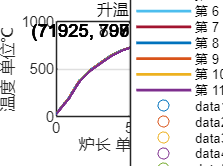

%物料第一层和中间层(最后一层)升温曲线
% % 获取所有处理区间的长度，并将其转换为 x 坐标区间长度
% process_vector = [cellZoneInfo{:,3}] * 1000;
% 
% % 初始化 x 坐标和 y 坐标
% x_total = [];
% y1_total = [];
% y11_total = [];
% 
% % 累积和计算 x 坐标
% x_start = 0;
% for i = 1:length(cellZoneInfo)
%     % 计算当前区间的 x 坐标
%     x_end = x_start + process_vector(i);
%     x = linspace(x_start, x_end, s_timeStep);
%     x_total = [x_total, x];
% 
%     % 创建当前区间的矩阵 
%     matrix = Temp_total(:, 1 + (i-1) * s_timeStep : i * s_timeStep);
% 
%     % 提取第一行和最后一行
%     y1 = matrix(1, :);
%     y11 = matrix(11, :);
% 
%     % 累积 y 坐标
%     y1_total = [y1_total, y1];
%     y11_total = [y11_total, y11];
% 
%     % 更新 x 起点
%     x_start = x_end;
% end
% 
% % 绘制折线图
% figure;
% plot(x_total, y1_total, 'r-', 'LineWidth', 1.5); 
% hold on;
% plot(x_total, y11_total, 'b-', 'LineWidth', 1.5);
% hold on;
% 
% % 添加图例和标签
% legend('表面温度', '中心温度');
% xlabel('炉长 单位:mm');
% ylabel('温度 单位℃');
% title('升温曲线');
% 
% % 显示网格
% grid on;
% 
% % 查找 x = 71925 对应的 y 值
% x_target = 71925;
% [~, idx] = min(abs(x_total - x_target)); % 找到最接近 x_target 的索引
% y1_target = y1_total(idx);
% y11_target = y11_total(idx);
% 
% % 在图中标注 x = 71925 时对应的 y 值
% plot(x_target, y1_target, 'ro'); % 在表面温度曲线上的标注
% text(x_target, y1_target, sprintf('(%d, %.2f)', x_target, y1_target), 'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'right');
% 
% plot(x_target, y11_target, 'bo'); % 在中心温度曲线上的标注
% text(x_target, y11_target, sprintf('(%d, %.2f)', x_target, y11_target), 'VerticalAlignment', 'top', 'HorizontalAlignment', 'left');
% 
% hold off;



%各层升温曲线
% 获取所有处理区间的长度，并将其转换为 x 坐标区间长度
process_vector = [cellZoneInfo{:,3}] * 1000;

% 初始化 x 坐标和 y 坐标
x_total = [];

% 累积和计算 x 坐标
x_start = 0;
for i = 1:length(cellZoneInfo)
    % 计算当前区间的 x 坐标
    x_end = x_start + process_vector(i);
    x = linspace(x_start, x_end, s_timeStep);
    x_total = [x_total, x];
    x_start = x_end;
end

% 绘制折线图
figure;

% 定义颜色列表
colors = lines(11); % 使用 lines 函数生成颜色

% 绘制每一行的数据
for row = 1:size(Temp_total, 1)
    % 提取当前行的所有区间数据
    y_total = [];
    for i = 1:length(cellZoneInfo)
        % 创建当前区间的矩阵 
        matrix = Temp_total(:, 1 + (i-1) * s_timeStep : i * s_timeStep);
        % 提取当前行数据
        y = matrix(row, :);
        y_total = [y_total, y];
    end
    % 绘制当前行的折线图
    plot(x_total, y_total, 'Color', colors(row, :), 'LineWidth', 1.5);
    hold on;
end

% 添加图例和标签
legend(arrayfun(@(x) sprintf('第 %d 层', x), 1:11, 'UniformOutput', false));
xlabel('炉长 单位:mm');
ylabel('温度 单位℃');
title('升温曲线');

% 显示网格
grid on;

% 查找 x = 71925 对应的 y 值
x_target = 71925;
[~, idx] = min(abs(x_total - x_target)); % 找到最接近 x_target 的索引

% 在图中标注 x = 71925 时对应的 y 值
for row = 1:size(Temp_total, 1)
    % 提取当前行的所有区间数据
    y_total = [];
    for i = 1:length(cellZoneInfo)
        % 创建当前区间的矩阵 
        matrix = Temp_total(:, 1 + (i-1) * s_timeStep : i * s_timeStep);
        % 提取当前行数据
        y = matrix(row, :);
        y_total = [y_total, y];
    end
    % 获取对应索引处的 y 坐标值
    y_target = y_total(idx);
    % 在折线图上标注
    plot(x_target, y_target, 'o', 'Color', colors(row, :)); 
    text(x_target, y_target, sprintf('(%d, %.2f)', x_target, y_target), 'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'right');
end

hold off;

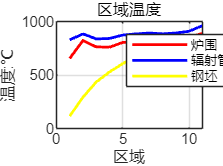





%三元各区域升温曲线
x = linspace(1,11,11);
yTw = Tw_zone - 237.15;
yTr = Tr_zone - 273.15;
yTs = Ts_zone - 273.15;

% 绘制折线图
figure;
plot(x, yTw, 'r-', 'LineWidth', 1.5);
hold on;
plot(x, yTr, 'b-', 'LineWidth', 1.5); 
hold on;
plot(x, yTs, 'y-', 'LineWidth', 1.5); 


% 添加图例和标签
legend('炉围', '辐射管', '钢坯');
xlabel('区域');
ylabel('温度:℃');
title('区域温度');

% 显示网格
grid on;
hold off;

**函数**

%计算空间角系数
%x为炉宽，m;h为炉高，m;y为炉段长度，m;h1为辐射管上端距炉墙高度，m;h2为辐射管下端距假象面p高度，m
function phi = phi_p1_w2(x, y, h1)
    X = x / h1;
    Y = y / h1;
    
    term1 = sqrt((1 + X^2) * (1 + Y^2)) / (1 + X^2 + Y^2);
    term2 = X * sqrt(1 + Y^2) * atan(X / sqrt(1 + Y^2));
    term3 = Y * sqrt(1 + X^2) * atan(Y / sqrt(1 + X^2));
    term4 = X * atan(X) + Y * atan(Y);
    
    phi = (2 / (pi * X * Y)) * (log(term1) + term2 + term3 - term4);
end

function phi = phi_p2_s(x, y, h2)
    X = x / h2;
    Y = y / h2;
    
    term1 = sqrt((1 + X^2) * (1 + Y^2)) / (1 + X^2 + Y^2);
    term2 = X * sqrt(1 + Y^2) * atan(X / sqrt(1 + Y^2));
    term3 = Y * sqrt(1 + X^2) * atan(Y / sqrt(1 + X^2));
    term4 = X * atan(X) + Y * atan(Y);
    
    phi = (2 / (pi * X * Y)) * (log(term1) + term2 + term3 - term4);
end

function phi = phi_p2_w1(x, y, h2)
    H = h2 / y;
    W = x / y;
    
    term1 = W * atan(1 / W) + H * atan(1 / H);
    term2 = sqrt(H^2 + W^2) * atan(1 / sqrt(H^2 + W^2));
    term3 = (1 + W^2) * (1 + H^2) / (1 + W^2 + H^2) * (W^2 * (1 + W^2 + H^2) / ((1 + W^2) * (W^2 + H^2)))^(W^2);
    term4 = (H^2 * (1 + H^2 + W^2) / ((1 + H^2) * (H^2 + W^2)))^(H^2);
    phi = (2 / (pi * W)) * (term1 - term2 + 1/4*log(term3 * term4));
end

function phi = phi_p2_w11(x, y, h2)
    % 定义H和W
    H = h2 / y;
    W = x / y;
    
    % 计算第一部分
    part1 = W * atan(1 / W) + H * atan(1 / H);
    
    % 计算第二部分
    part2 = sqrt(H^2 + W^2) * atan(1 / sqrt(H^2 + W^2));
    
    % 计算第三部分中的内部分数
    term1_numerator = (1 + W^2) * (1 + H^2);
    term1_denominator = 1 + W^2 + H^2;
    term1 = term1_numerator / term1_denominator;
    
    term2_numerator = W^2 * (1 + W^2 + H^2);
    term2_denominator = (1 + W^2) * (W^2 + H^2);
    term2 = term2_numerator / term2_denominator;
    term2 = term2^(W^2);
    
    term3_numerator = H^2 * (1 + H^2 + W^2);
    term3_denominator = (1 + H^2) * (H^2 + W^2);
    term3 = term3_numerator / term3_denominator;
    term3 = term3^(H^2);
    
    % 计算第三部分
    part3 = (1/4) * log(term1 * term2 * term3);
    
    % 计算最终结果
    phi = (2 / (pi * W)) * (part1 - part2 + part3);
    
end

%全交换面积计算

function SR = calculate_SR(Fr, Fw, Fs, epsilon_r, epsilon_s, rho_r, rho_w, rho_s, Xrr, Xws, Xsr, Xww, Xwr)
    % 计算 SR
    numerator = -Fr * epsilon_r * Fs * epsilon_s * (-Fw * rho_w * Xwr * Xws + Fs * Xsr * (-1 + rho_w * Xww));
    denominator = Fr * (-1 + rho_r * Xrr) * (Fw * rho_s * rho_w * Xws^2 + Fs * (-1 + rho_w * Xww)) ...
                  + Fs * rho_r * (-Fw * rho_w * Xwr * (Xwr + 2 * rho_s * Xsr * Xws) + Fs * rho_s * Xsr^2 * (-1 + rho_w * Xww));
    SR = numerator / denominator;
end

function SW = calculate_SW(Fr, Fw, Fs, epsilon_w, epsilon_s, rho_r, rho_w, rho_s, Xrr, Xws, Xwr, Xsr, Xww)
    % 计算 SW
    numerator = Fw * epsilon_w * Fs * epsilon_s * (Fs * rho_r * Xsr * Xwr + Fr * (1 - rho_r * Xrr) * Xws);
    denominator = Fr * (-1 + rho_r * Xrr) * (Fw * rho_s * rho_w * Xws^2 + Fs * (-1 + rho_w * Xww)) ...
                  + Fs * rho_r * (-Fw * rho_w * Xwr * (Xwr + 2 * rho_s * Xsr * Xws) + Fs * rho_s * Xsr^2 * (-1 + rho_w * Xww));
    SW = numerator / denominator;
end

function WR = calculate_WR(Fr, Fw, Fs, epsilon_r, epsilon_w, rho_r, rho_w, rho_s, Xrr, Xwr, Xsr, Xsw, Xww)
    % 计算 WR
    numerator = Fr * epsilon_r * Fw * epsilon_w * (Fs * rho_s * Xsr * Xsw + Fw * Xwr);
    denominator = -Fr * (-1 + rho_r * Xrr) * (Fs * rho_s * rho_w * Xsw^2 + Fw * (-1 + rho_w * Xww)) ...
                  + Fw * rho_r * (Fw * rho_w * Xwr^2 + Fs * rho_s * Xsr * (Xsr + 2 * rho_w * Xsw * Xwr - rho_w * Xsr * Xww));
    WR = -numerator / denominator;
end

%TDMA求解表面显示中心隐式差分
%热流 离散层数 密度 时间步长 空间步长 上一时刻温度场
function T = TDMA_s(Qcon,N,density,delta_t,delta_x,T)
    %初始化
    Cp_point = zeros(1,N+1);
    Lambda_point = zeros(1,N+1);

    for i = 1 : N+1
        [Cp_point(i) , Lambda_point(i)] = calPhysicalParameters(1 , T(i));
    end
    Cp_layer = computeAdjacentAverages(Cp_point);
    Lambda_Layer = computeAdjacentHarmonicAverages(Lambda_point);
    Fo = Lambda_Layer./(density.*Cp_layer)*delta_t/(delta_x^2);
    
    %边界节点计算
    T(1) = T(1) + 2*Fo(1)*(T(2) - T(1) + Qcon*delta_x/Lambda_Layer(1));
    T(N+1) = T(N+1) + 2*Fo(N)*(T(N) - T(N+1));

    %Thomas算法内部节点计算
    a = -Fo(2:N-1);
    b = 1 + computeAdjacentSums(Fo);
    c = -Fo(2:N-1);
    d = T(2:N);
    d(1) = d(1) + Fo(1) * T(1);
    d(N-1) = d(N-1) + Fo(N) * T(N+1);
    
    x = tridiagonal_vector(a,b,c,d);%三对角矩阵算法
    % 检查向量长度以确保可以替换
    if length(T) < 2 || length(x) ~= length(T) - 2
        error('向量 T 和 x 的长度不匹配，无法进行替换');
    end
    % 替换 T 的第 2 到第 N 个元素为 x 的第 1 到第 N-1 个元素
    T(2:end-1) = x;
end


%计算相邻两元素的算术平均值
function avgArray = computeAdjacentAverages(inputArray)
    % 检查输入是否为非空的一维数组
    if isempty(inputArray) || ~isvector(inputArray)
        error('输入必须是一个非空的一维数组');
    end

    % 获取输入数组的长度
    n = length(inputArray);

    % 如果输入数组的长度小于2，无法计算相邻元素的平均值
    if n < 2
        error('输入数组的长度必须至少为2');
    end

    % 预分配输出数组
    avgArray = zeros(1, n-1);

    % 计算相邻元素的算术平均值
    for i = 1:n-1
        avgArray(i) = (inputArray(i) + inputArray(i+1)) / 2;
    end
end


%计算相邻两元素的调和平均值
function harmonicAvgArray = computeAdjacentHarmonicAverages(inputArray)
    % 检查输入是否为非空的一维数组
    if isempty(inputArray) || ~isvector(inputArray)
        error('输入必须是一个非空的一维数组');
    end

    % 获取输入数组的长度
    n = length(inputArray);

    % 如果输入数组的长度小于2，无法计算相邻元素的调和平均值
    if n < 2
        error('输入数组的长度必须至少为2');
    end

    % 预分配输出数组
    harmonicAvgArray = zeros(1, n-1);

    % 计算相邻元素的调和平均值
    for i = 1:n-1
        harmonicAvgArray(i) = 2 / (1/inputArray(i) + 1/inputArray(i+1));
    end
end

%计算两相邻元素的加和
function sumArray = computeAdjacentSums(inputArray)
    % 检查输入是否为非空的一维数组
    if isempty(inputArray) || ~isvector(inputArray)
        error('输入必须是一个非空的一维数组');
    end

    % 获取输入数组的长度
    n = length(inputArray);

    % 如果输入数组的长度小于2，无法计算相邻元素的和
    if n < 2
        error('输入数组的长度必须至少为2');
    end

    % 预分配输出数组
    sumArray = zeros(1, n-1);

    % 计算相邻元素的和
    for i = 1:n-1
        sumArray(i) = inputArray(i) + inputArray(i+1);
    end
end


